# **Wireless Communication**

## `Computer Assignment 3 `

### `Fatemeh Jalili - 810199398`

## **Problem #1 - OFDM**

### **Part 5**

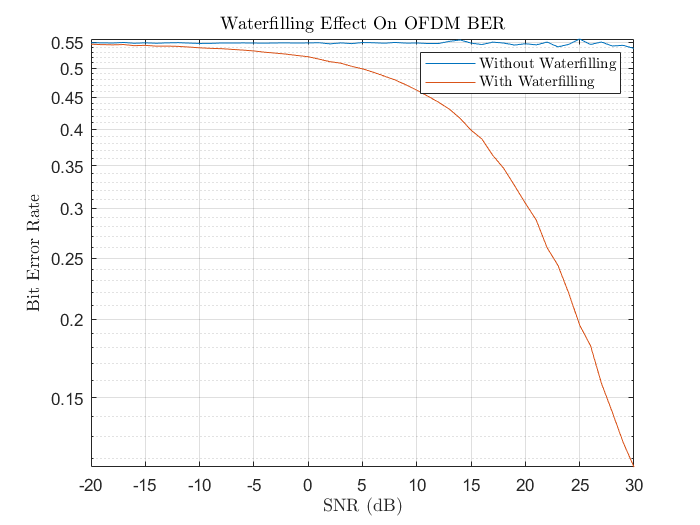

clc, clear, close all;

% Parameters
BW = 20e6;
Tc = 5e-3;
Td = 10e-6;
N = 1e6;
nc = 65536;
L = int32(BW * Td);
cpLength = L - 1;
blockNum = ceil(N / nc);
Pmax = nc / 4;
hPower = 1;
%

xm = 2 * randi([1, 2], 1, N) - 3;
X = reshape([xm, zeros(1, nc - mod(N, nc))], nc, blockNum).';

SNR_dB = -20 : 30; %dB
SNR = 10 .^ (SNR_dB ./ 10);
N0Array = Pmax ./ (nc .* SNR);

berList = [];
berListWF = [];
for N0 = N0Array
    numErrorBits = 0;
    numErrorBitsWF = 0;
    for i = 1 : blockNum
        x = X(i, :);
        h = sqrt(hPower / 2) * (randn(1, L) + 1i * randn(1, L));
        H = fft(h ,nc);
        AWF = waterfilling(x, N0, H, Pmax);
        A = sqrt(Pmax / nc) * x;
        aWF = ifft(AWF, nc);
        a = ifft(A, nc);
        tWF = [aWF(nc - cpLength + 1 : end), aWF];
        t = [a(nc - cpLength + 1 : end), a];
        
        noise =  sqrt(N0 / 2) * (randn(1, nc + 2 * cpLength) + 1i * randn(1, nc + 2 * cpLength));
        rWF = conv(tWF, h) + noise;
        r = conv(t, h) + noise;
        yWF = rWF(cpLength + 1 : cpLength + nc);
        y = r(cpLength + 1 : cpLength + nc);
        YWF = fft(yWF, nc);
        Y = fft(y, nc);
        
        xHatWF = real(YWF) > 0;
        xHat = real(Y) > 0;
        numErrorBitsWF = numErrorBitsWF + sum((2 * xHatWF - 1) ~= x);
        numErrorBits = numErrorBits + sum((2 * xHat - 1) ~= x);
    end
    berWF = numErrorBitsWF / N;
    ber = numErrorBits / N;
    berListWF = [berListWF, berWF];
    berList = [berList, ber];
end

figure;
semilogy(SNR_dB, berList)
hold on
semilogy(SNR_dB, berListWF)
grid on
title('Waterfilling Effect On OFDM BER','Interpreter','latex');
xlabel('SNR (dB)','Interpreter','latex');
ylabel('Bit Error Rate','Interpreter','latex');
legend('Without Waterfilling', 'With Waterfilling','Interpreter','latex')

### **Part 6**

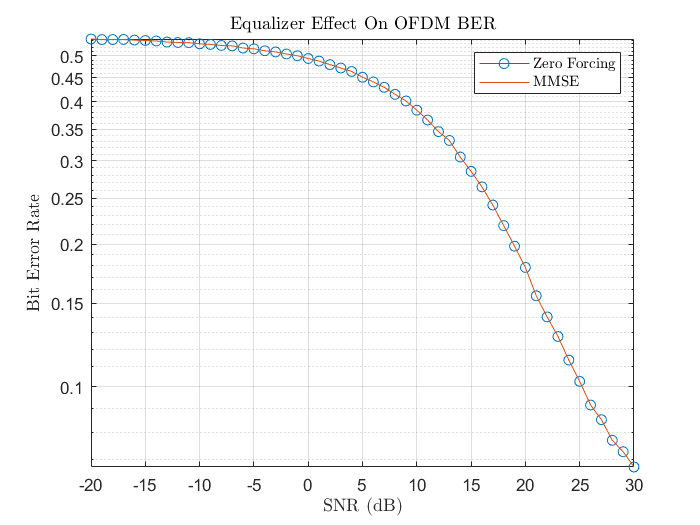

berListZF = [];
berListMMSE = [];
for N0 = N0Array
    numErrorBitsZF = 0;
    numErrorBitsMMSE = 0;
    for i = 1 : blockNum
        x = X(i, :);
        h = sqrt(hPower / 2) * (randn(1, L) + 1i * randn(1, L));
        H = fft(h ,nc);
        a = ifft(x, nc);
        t = [a(nc - cpLength + 1 : end), a];
        
        noise =  sqrt(N0 / 2) * (randn(1, nc + 2 * cpLength) + 1i * randn(1, nc + 2 * cpLength));
        r = conv(t, h) + noise;
        y = r(cpLength + 1 : cpLength + nc);
        Y = fft(y, nc);
        
        Wk_ZF = 1 ./ H;
        Wk_MMSE = conj(H) ./ (abs(H) .^ 2 + N0);
        xHatZF = real(Y .* Wk_ZF) > 0;
        xHatMMSE = real(Y .* Wk_MMSE) > 0;
        numErrorBitsZF = numErrorBitsZF + sum((2 * xHatZF - 1) ~= x);
        numErrorBitsMMSE = numErrorBitsMMSE + sum((2 * xHatMMSE - 1) ~= x);
    end
    berZF = numErrorBitsZF / N;
    berMMSE = numErrorBitsMMSE / N;
    berListZF = [berListZF, berZF];
    berListMMSE = [berListMMSE, berMMSE];
end

figure;
semilogy(SNR_dB, berListZF,'-o')
hold on
semilogy(SNR_dB, berListMMSE)
grid on
title('Equalizer Effect On OFDM BER','Interpreter','latex');
xlabel('SNR (dB)','Interpreter','latex');
ylabel('Bit Error Rate','Interpreter','latex');
legend('Zero Forcing', 'MMSE','Interpreter','latex')

### Part 7

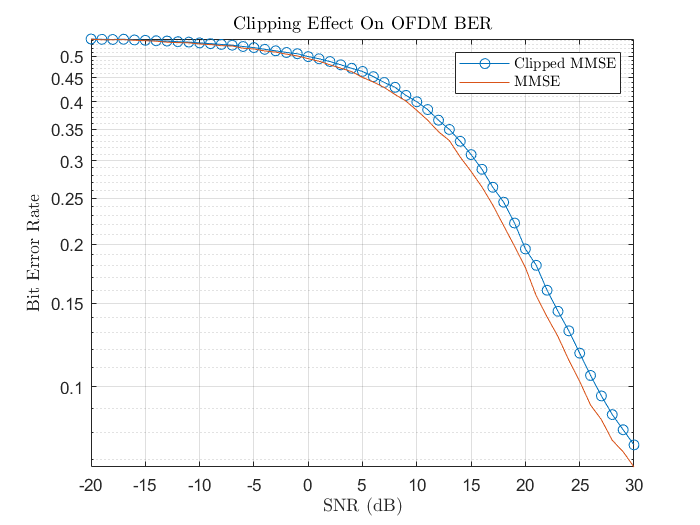

berListMMSE_clip = [];
ratio = 0.4;
for N0 = N0Array
    numErrorBitsMMSE = 0;
    for i = 1 : blockNum
        x = X(i, :);
        h = sqrt(hPower / 2) * (randn(1, L) + 1i * randn(1, L));
        H = fft(h ,nc);
        a = ifft(x, nc);
        t = clipping([a(nc - cpLength + 1 : end), a], ratio);
        
        noise =  sqrt(N0 / 2) * (randn(1, nc + 2 * cpLength) + 1i * randn(1, nc + 2 * cpLength));
        r = conv(t, h) + noise;
        y = r(cpLength + 1 : cpLength + nc);
        Y = fft(y, nc);
        
        Wk_MMSE = conj(H) ./ (abs(H) .^ 2 + N0);
        xHatMMSE = real(Y .* Wk_MMSE) > 0;
        numErrorBitsMMSE = numErrorBitsMMSE + sum((2 * xHatMMSE - 1) ~= x);
    end
    berMMSE = numErrorBitsMMSE / N;
    berListMMSE_clip = [berListMMSE_clip, berMMSE];
end

figure;
semilogy(SNR_dB, berListMMSE_clip,'-o')
hold on
semilogy(SNR_dB, berListMMSE)
grid on
title('Clipping Effect On OFDM BER','Interpreter','latex');
xlabel('SNR (dB)','Interpreter','latex');
ylabel('Bit Error Rate','Interpreter','latex');
legend('Clipped MMSE', 'MMSE','Interpreter','latex')

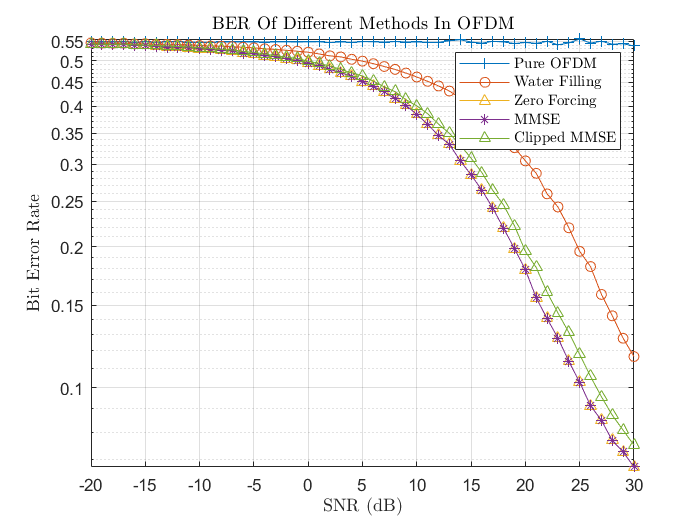

figure;
semilogy(SNR_dB, berList,'-+', SNR_dB, berListWF,'-o', SNR_dB, berListZF,'-^',...
    SNR_dB, berListMMSE,'-*', SNR_dB, berListMMSE_clip, '-^' )
grid on
title('BER Of Different Methods In OFDM','Interpreter','latex');
xlabel('SNR (dB)','Interpreter','latex');
ylabel('Bit Error Rate','Interpreter','latex');
legend('Pure OFDM','Water Filling','Zero Forcing', 'MMSE', 'Clipped MMSE', 'Interpreter','latex')

functions:

function A = waterfilling(x, N0, H, Pmax)
    func = @(lambda) Pmax - sum(max((1 ./ lambda) - (N0./ abs(H).^2), 0));
    lambdaHat = fzero(func, [1e-4, 1 / min(N0 ./ abs(H).^2)]);
    P = max((1./ lambdaHat) - (N0./ abs(H).^2), 0);
    W = sqrt(P) .* exp(-1i * angle(H));
    A = x .* W;
end

function t = clipping(a, ratio)
    thr = ratio * max(abs(a));
    a(abs(a) > thr) = thr * exp(1j * angle(a(abs(a) > thr)));
    t = a;
end